# Latent Variable Example

This example shows the relationship between the X loadings from the SIMPLS algorithm and the latent variables.

Copyright 2022 Battelle Memorial Institute

load pnnl_napalm_data

Compute the mean-centered X loadings from the mean-centered SIMPLS algorithm.

nLatentVariables = 10;

X = A_train;
Y = C_train;

X0 = X - mean(X,1);
Y0 = Y - mean(Y,1);

[X_loadings, Y_loadings, X_scores, Y_scores, Weights] = pnnl_simpls(X0, Y0, nLatentVariables);

The latent variables (LV) are the rectified and normalized X loadings from the SIMPLS algorithm.  The X loadings are column-oriented, so transpose them so the latent variables will be row-oriented.

LV = pnnl_normalize_rows(pnnl_rectify_rows(X_loadings'));

Plot the first five loadings

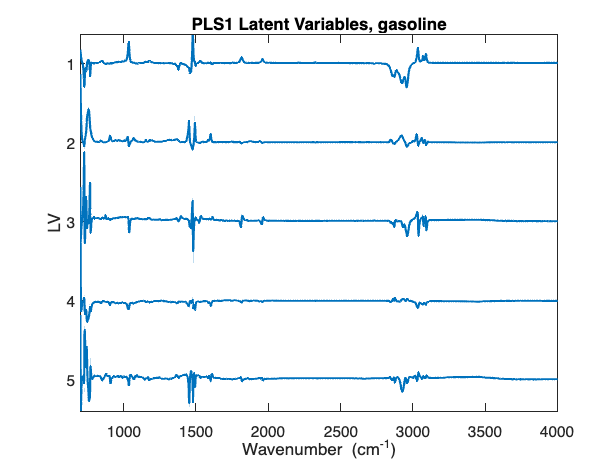

pnnl_strip_plot(Wavenumbers,LV(1:5,:),'PLS1 Latent Variables, gasoline',WavenumberLabel,'LV')

Disclaimer

This material was prepared as an account of work sponsored by an agency of the United States Government. Neither the United States Government nor the United States Department of Energy, nor Battelle, nor any of their employees, nor any jurisdiction or organization that has cooperated in the development of these materials, makes any warranty, express or implied, or assumes any legal liability or responsibility for the accuracy, completeness, or usefulness or any information, apparatus, product, software, or process disclosed, or represents that its use would not infringe privately owned rights.

Reference herein to any specific commercial product, process, or service by trade name, trademark, manufacturer, or otherwise does not necessarily constitute or imply its endorsement, recommendation, or favoring by the United States Government or any agency thereof, or Battelle Memorial Institute. The views and opinions of authors expressed herein do not necessarily state or reflect those of the United States Government or any agency thereof.

PACIFIC NORTHWEST NATIONAL LABORATORY

operated by

BATTELLE

for the

UNITED STATES DEPARTMENT OF ENERGY

under Contract DE-AC05-76RL01830